mystartdefaults
BZpath


Function BZpath: 4 segments
Segment 1: direction [-1 -1 -1]'
Segment 2: direction [1 0 0]'
Segment 3: direction [-1 -1 0]'
Segment 4: direction [-1 -1 0]'
q1         q2         q3         Magnitude       LinearCoord     SegmentID      
0.500      0.500      0.500      0.866           0.000           1              
0.480      0.480      0.480      0.831           0.020           1              
0.460      0.460      0.460      0.797           0.040           1              
0.440      0.440      0.440      0.762           0.060           1              
0.420      0.420      0.420      0.727           0.080           1              
0.400      0.400      0.400      0.693           0.100           1              
0.380      0.380      0.380      0.658           0.120           1              
0.360      0.360      0.360      0.624           0.140           1              
0.340      0.340      0.340      0.589           0.160           1              
0.320      0.320      0.320      0

ans =     0.5000    0.4800    0.4600    0.4400    0.4200    0.4000    0.3800    0.3600    0.3400    0.3200    0.3000    0.2800    0.2600    0.2400    0.2200    0.2000    0.1800    0.1600    0.1400    0.1200    0.1000    0.0800    0.0600    0.0400    0.0200         0         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600
    0.5000    0.4800    0.4600    0.4400    0.4200    0.4000    0.3800    0.3600    0.3400    0.3200    0.3000    0.2800    0.2600    0.2400    0.2200    0.2000    0.1800    0.1600    0.1400    0.1200    0.1000    0.0800    0.0600    0.0400    0.0200         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

CohenBergstresser1966
recipunit = 1.e+10;
ekinscale = ((hbar*recipunit)^2/(2*elm))/qel; 
k_points = ans(1:3,:);

Unit vectors in reciprocal space

g = zeros(4,3);
g(1:3,1) = cross(a(:,2),a(:,3))/cell_volume;
g(1:3,2) = cross(a(:,3),a(:,1))/cell_volume;
g(1:3,3) = cross(a(:,1),a(:,2))/cell_volume;

for i = 1:3
    g(4, i) = dot(g(1:3, i), g(1:3, i));
end
disp(g)

     1    -1     1
     1     1    -1
    -1     1     1
     3     3     3



 Build reciprocal lattice

min_norm = sqrt(min(g(4,:)));
limit = ceil(sqrt(sqrt(cutoff))/min_norm);
nodes = (2 * limit + 1)^3;
G_vectors = zeros(5,nodes);
n = 0;
% Loop to generate G vectors
% Equation 3.17
for h = -limit:limit
    for k = -limit:limit
        for l = -limit:limit
            n=n+1;
            G_vectors(1:3,n) = h * g(1:3,1) + k * g(1:3,2) + l * g(1:3,3);
            G_vectors(5,n) = dot(G_vectors(1:3,n),G_vectors(1:3,n));
            G_vectors(4,n) = sqrt(G_vectors(5,n));
        end
    end
end
disp(G_vectors)

   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000   -6.0000   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000    4.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000   -4.0000   -3.0000   -2.0000   -1.0000         0    1.0000    2.0000    3.0000    4.0000    5.0000         0    1.0000    2.0000    3.0000    4.0000   -1.0000         0    1.0000    2.0000    3.0000   -2.0000   -1.0000         0    1.0000    2.0000   -3.0000   -2.0000   -1.0000         0    1.0000

G = sortrows(G_vectors', 4)';
disp(G)

         0   -1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000    1.0000         0   -2.0000         0         0    2.0000         0   -2.0000         0   -2.0000         0   -2.0000    2.0000   -2.0000    2.0000         0    2.0000         0    2.0000   -1.0000   -3.0000   -1.0000   -3.0000   -1.0000    1.0000    1.0000   -3.0000   -3.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000    3.0000    3.0000   -1.0000   -1.0000    1.0000    3.0000    1.0000    3.0000    1.0000   -2.0000   -2.0000    2.0000   -2.0000    2.0000   -2.0000    2.0000    2.0000         0   -4.0000         0         0    4.0000         0   -1.0000   -3.0000    1.0000   -3.0000    3.0000    3.0000   -3.0000   -3.0000    3.0000   -1.0000    3.0000    1.0000         0   -4.0000    2.0000   -4.0000         0   -2.0000    2.0000         0    4.0000   -2.0000    4.0000         0   -2.0000    2.0000   -4.0000    4.0000   -2.0000    2.0000    1.0000   -5.0000   -1.0000    1.0000    5.0000

Cutoff

num_G_vectors=1;
for n = 2:nodes
    if(G(5,n) <= cutoff)
        num_G_vectors=num_G_vectors + 1;
    end
end

Loops for VG


H = zeros(num_G_vectors, num_G_vectors);
G_diff = zeros(5,1);
for n = 1:num_G_vectors
    VG(n) = 0;
    VS = 0;
    VA = 0;
    if G(5,n)==0
        VS = ff(m,1) * Rydberg;
        VA = 0;
    elseif G(5,n) == 3
        VS = ff(m,2) * Rydberg; 
        VA = ff(m,5) * Rydberg;
    elseif G(5,n) == 4
        VS = 0; 
        VA = ff(m,6) * Rydberg;
    elseif G(5,n) == 8
        VS = ff(m,3) * Rydberg; 
        VA = 0;
    elseif G(5,n) == 11
        VS = ff(m,4) * Rydberg; 
        VA = ff(m,7) * Rydberg;
    end
    % Equation 3.107
    VG(n) = VS * cos(2 * pi * dot(G(1:3,n),tau(1:3,1))) - 1i * VA * sin(2 * pi * dot(G(1:3,n),tau(1:3,1)));
end
VG

VG =   -10.4823    2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203    2.0203         0         0         0         0         0         0   -0.5442   -0.5442   -0.5442    0.5442    0.5442    0.5442    0.5442    0.5442    0.5442   -0.5442   -0.5442   -0.5442   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697    0.7697   -0.7697    0.7697    0.7697   -0.7697   -0.7697   -0.7697   -0.7697    0.7697    0.7697   -0.7697    0.7697   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697


Hamiltonian

for j=1:num_G_vectors
    for i=1:num_G_vectors
        G_diff(1:3) = G(1:3,i) - G(1:3,j);
        G_diff(5) = dot(G_diff(1:3),G_diff(1:3));
        if(G_diff(5) <= Gs_max)
            for k=1:num_G_vectors
                if norm(G_diff(1:3)-G(1:3,k)) < tol
                    H(i,j) = VG(k);
                end
            end
        end
    end 
end
disp(H)

  -10.4823    2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203    2.0203         0         0         0         0         0         0   -0.5442   -0.5442   -0.5442    0.5442    0.5442    0.5442    0.5442    0.5442    0.5442   -0.5442   -0.5442   -0.5442   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697    0.7697   -0.7697    0.7697    0.7697   -0.7697   -0.7697   -0.7697   -0.7697    0.7697    0.7697   -0.7697    0.7697   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697   -0.7697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.0203  -10.4823         0         0         0   -0.5442   -0.5442   -0.5442         0   -2.0203   -2.020

Kinetic energy + plotting

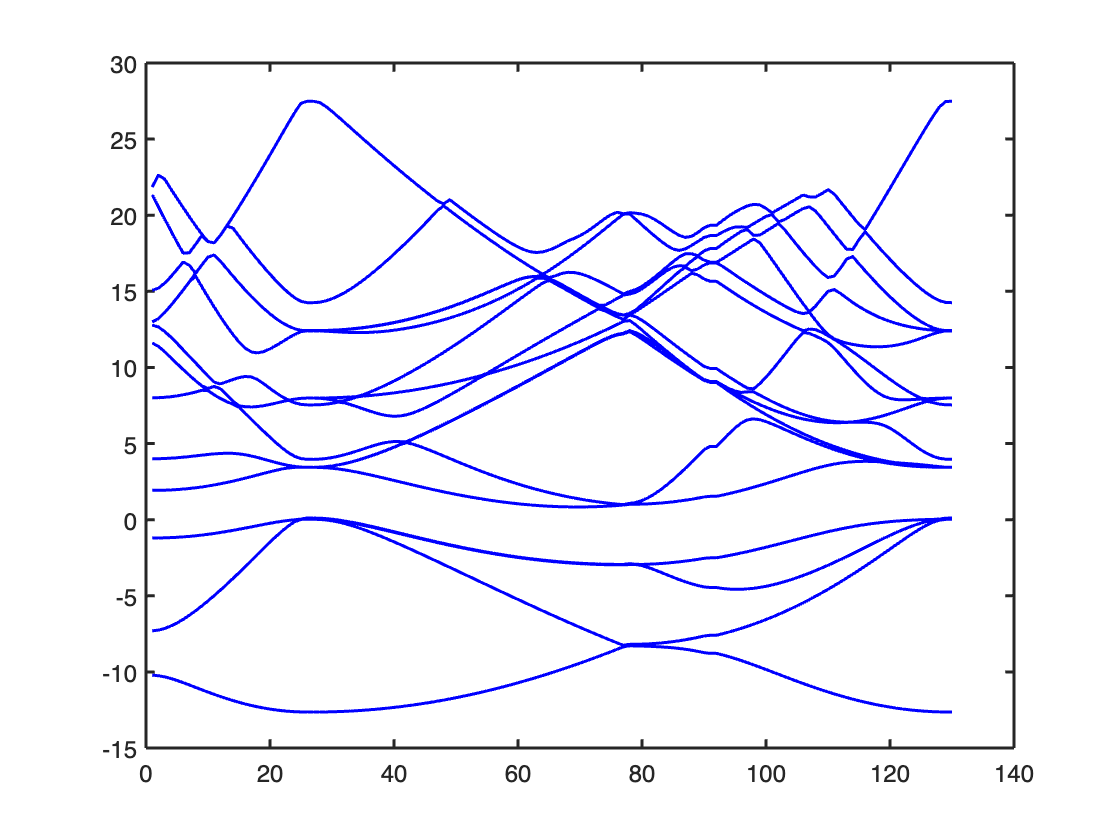

spacing = ls(m);
ekinunit = ekinscale*(2*pi/spacing)^2;
num_k_points = 1:size(k_points,2);
for i = 1:size(k_points,2)
    for j = 1:num_G_vectors
        for k = 1:size(k_points,1)
            p(k)=k_points(k,i) - G(k,j);
        end
        H(j,j) = ekinunit * (dot(p,p)) + VG(1);
    end
    [v,ev]=eig(H);
    E=real(diag(ev));
    [E,perm]=sort(E);
    v=v(:,perm);
    for g=1:nband
        bandstructure(g,i) = E(g);
    end
end

plot(num_k_points,bandstructure,'Color','blue','MarkerSize',2);

disp(bandstructure)

  -10.2163  -10.2503  -10.3249  -10.4320  -10.5623  -10.7074  -10.8608  -11.0175  -11.1739  -11.3274  -11.4759  -11.6182  -11.7532  -11.8801  -11.9982  -12.1071  -12.2064  -12.2959  -12.3752  -12.4443  -12.5030  -12.5511  -12.5887  -12.6155  -12.6316  -12.6370  -12.6370  -12.6352  -12.6298  -12.6209  -12.6083  -12.5922  -12.5725  -12.5492  -12.5224  -12.4920  -12.4580  -12.4204  -12.3794  -12.3348  -12.2866  -12.2349  -12.1797  -12.1211  -12.0589  -11.9932  -11.9241  -11.8515  -11.7755  -11.6961  -11.6133  -11.5271  -11.4375  -11.3446  -11.2483  -11.1488  -11.0459  -10.9399  -10.8306  -10.7181  -10.6024  -10.4836  -10.3617  -10.2368  -10.1088   -9.9778   -9.8439   -9.7071   -9.5674   -9.4249   -9.2796   -9.1317   -8.9810   -8.8278   -8.6720   -8.5138   -8.3532   -8.2879   -8.2943   -8.3034   -8.3160   -8.3329   -8.3549   -8.3830   -8.4181   -8.4614   -8.5138   -8.5766   -8.6503   -8.7356   -8.7826   -8.7826   -8.8851   -8.9985   -9.1220   -9.2543   -9.3941   -9.5398   -9.6900   -9.8433

% csvwrite('bandstructure_insb_fix.csv', bandstructure);

fasdklfj

%find maximum/ridberg
max(bandstructure(3,:))/Rydberg

ans = 0.0019